% demos for ch06

## Kernel regression with gaussian kernel

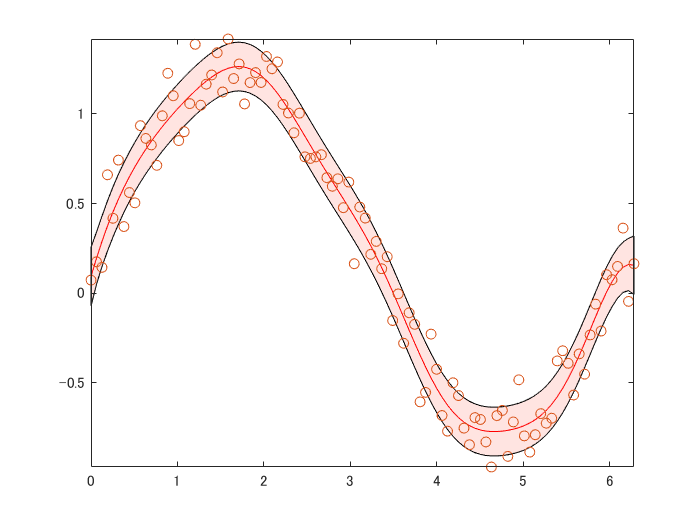

clear; close all;
n = 100;
x = linspace(0,2*pi,n);   % test data
t = sin(x)+rand(1,n)/2;
model = knReg(x,t,1e-4,@knGauss);
[y,s] = knRegPred(model,x);
plotCurveBar(x,y,s);
hold on;
plot(x,t,'o');
hold off;